# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';

### Chapter 6: 短期性分析第二种路径（基于时间序列特征的谱系分类）

#### 5.1 构造特征

% 导入数据
country_SA = StatisticsAnalysis('TablePath', path_country);
country = country_SA.Table;
daily_SA = StatisticsAnalysis('TablePath', path_daily, ...
    'ImportOptions', {'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}} ...
    );
daily = daily_SA.Table;
% 每日数据所涉及的国家
daily_location = unique(daily{:,'location'});
% 国家数据中被涉及的、无缺的的行
country_location = unique(country{:,'location'});
%     country_daily = country;
country_daily = country(ismember(country_location, daily_location), :);
country_daily(any(ismissing(country_daily)')',:) = [];
% 疫情管控力度、累计病例-总人口比
MeanStingency = zeros(size(country_daily, 1), 1);
StdStingency = MeanStingency;
CasesPerCapita = MeanStingency;
for idx = 1: size(country_daily, 1)
    tp = daily_SA.WholeTable{strcmp(daily_SA.WholeTable.location,country_daily{idx, 'location'}),'stringency_index'};
    MeanStingency(idx) = tsnanmean(tp);
    StdStingency(idx) = tsnanstd(tp);
    tp = daily_SA.WholeTable{strcmp(daily_SA.WholeTable.location,country_daily{idx, 'location'}),'total_cases'};
    CasesPerCapita(idx) = tsnanmax(tp) / country_daily{idx, 'population'};
end
country_daily = addvars(country_daily, MeanStingency, 'NewVariableNames', 'stingency_index_Mean');
country_daily = addvars(country_daily, StdStingency, 'NewVariableNames', 'stingency_index_std');
country_daily = addvars(country_daily, CasesPerCapita, 'NewVariableNames', 'total_cases_per_capita');
% 数据准备
country_daily = removevars(country_daily, {'continent', 'population', 'gdp_per_capita'});
country_daily = addvars(country_daily, (country_daily.male_smokers+country_daily.female_smokers)/2, 'NewVariableNames', 'smokers');
country_daily = removevars(country_daily, {'male_smokers', 'female_smokers'});
data = table2array(removevars(country_daily,'location'));

5.2 谱系分类

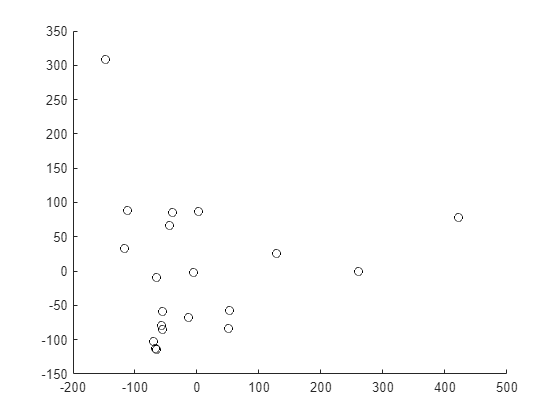

% 主成分分析
[coeff, score, latent] = pca(data);
ratio = latent/sum(latent);
data_cut = score(:,3:end);
% dbscan
% idxx = dbscan(data_cut, 65, 2);
% k-mean
idxx = kmeans(data, 4);
figure(1); scatter(score(:,1), score(:,2), 'black');

country_types = cell(length(unique(abs(idxx))),1);
noise_points = cell.empty;
for ii = 1:size(idxx,1)
    type = idxx(ii,1);
    if type == -1
        display(['noise point ', country_daily{ii,'location'}{1}]);
        noise_points = [noise_points, country_daily{ii,'location'}];
    else
        country_types{type,1} = [country_types{type,1}, country_daily{ii,'location'}];
    end
end
% 显示分类
for ii = 1: size(country_types,1), country_types{ii,2} = length(country_types{ii,1}); end
[~, index] = sort(cell2mat(country_types(:,2)));
country_types = country_types(index, 1);
for ii = 1: size(country_types,1), display(country_types{ii,1}); end

  1×1 cell array

    {'Egypt'}

  1×2 cell array

    {'Japan'}    {'South Korea'}

  1×5 cell array

  Columns 1 through 4

    {'China'}    {'Hungary'}    {'Malaysia'}    {'Saudi Arabia'}

  Column 5

    {'Zimbabwe'}

  1×12 cell array

  Columns 1 through 5

    {'Australia'}    {'Canada'}    {'Chile'}    {'Ethiopia'}    {'France'}

  Columns 6 through 10

    {'Germany'}    {'Iceland'}    {'Ireland'}    {'South Africa'}    {'Sweden'}

  Columns 11 through 12

    {'Thailand'}    {'United States'}



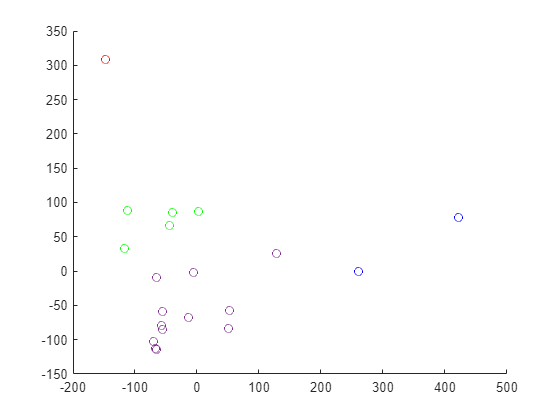

% 可视化分类结果
color = {'r', 'b', 'g', 'o', 'y', 'cyan'};
for ii = 1: size(country_types,1)
    map = ismember(country_daily{:,'location'},country_types{ii,1});
    figure(2); scatter(score(map,1), score(map,2), color{ii}); hold on
end
map = ismember(country_daily{:,'location'},noise_points);
figure(2); scatter(score(map,1), score(map,2), 'black'); hold off

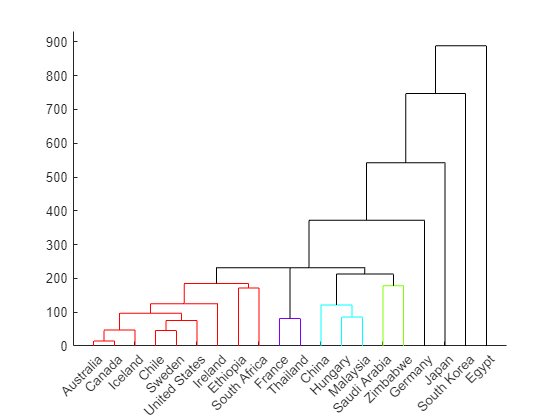

daily = 343×2 timetable
       date       new_vaccinations    total_vaccinations
    __________    ________________    __________________

    2020-01-24          NaN                  NaN        
    2020-01-25          NaN                  NaN        
    2020-01-26          NaN                  NaN        
    2020-01-27          NaN                  NaN        
    2020-01-28          NaN                  NaN        
    2020-01-29          NaN                  NaN        
    2020-01-30          NaN                  NaN        
    2020-01-31          NaN                  NaN        
    2020-02-01          NaN                  NaN        
    2020-02-02          NaN                  NaN        
    2020-02

daily2 = 343×2 timetable
       date       new_cases    total_cases
    __________    _________    ___________

    2020-01-24        2             2     
    2020-01-25        1             3     
    2020-01-26        0             3     
    2020-01-27        0             3     
    2020-01-28        1             4     
    2020-01-29        1             5     
    2020-01-30        0             5     
    2020-01-31        0             5     
    2020-02-01        1             6     
    2020-02-02        0             6     
    2020-02-03        0             6     
    2020-02-04        0             6     
    2020-02-05        0             6     
    <s

ans = struct with fields:
            Map: [343×3 logical]
           date: {}
      new_cases: {1×8 cell}
    total_cases: {}


daily2 = 343×2 timetable
       date       new_cases    total_cases
    __________    _________    ___________

    2020-01-24        2             2     
    2020-01-25        1             3     
    2020-01-26        0             3     
    2020-01-27        0             3     
    2020-01-28        1             4     
    2020-01-29        1             5     
    2020-01-30        0             5     
    2020-01-31        0             5     
    2020-02-01        1             6     
    2020-02-02        0             6     
    2020-02-03        0             6     
    2020-02-04        0             6     
    2020-02-05        0             6     
    <s

ans = struct with fields:
              Increment: 'new_cases'
               Addition: 'total_cases'
         IncrementWhere: [0 1 0]
          AdditionWhere: [0 0 1]
    IncrementMissingMap: [343×1 logical]
     AdditionMissingMap: [343×1 logical]
     DecreasingAddition: {1×9 cell}
          MissingBlocks: [8×1 struct]
        tpMissingBlocks: [8×1 struct]
     MissingBlocksGroup: [8×1 struct]


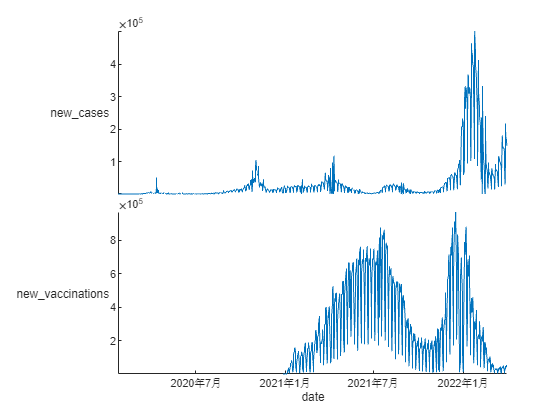

ans =   TimetableProperties with properties:

               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [799×1 datetime]
                 StartTime: 2020-01-24
                SampleRate: NaN
                  TimeStep: 1d

   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [799 3]
                  TagNames: {{2×1 cell}  {2×1 cell}}
               UniqueCount: {[748]  [460]}
                ValueClass: {'double'  'double'}
              MissingCount: {[10]  [339]}
              MissingRatio: {[0.01

daily2 = 799×12 timetable
       date        location     continent     new_cases    total_cases    new_tests    total_tests    positive_rate    new_vaccinations    total_vaccinations    hosp_patients    icu_patients    stringency_index
    __________    __________    __________    _________    ___________    _________    ___________    _____________    ________________    __________________    _____________    ____________    ________________

    2020-01-24    {'France'}    {'Europe'}        2             2            NaN           N

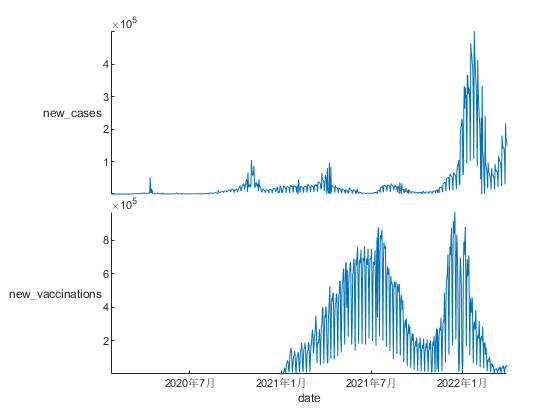

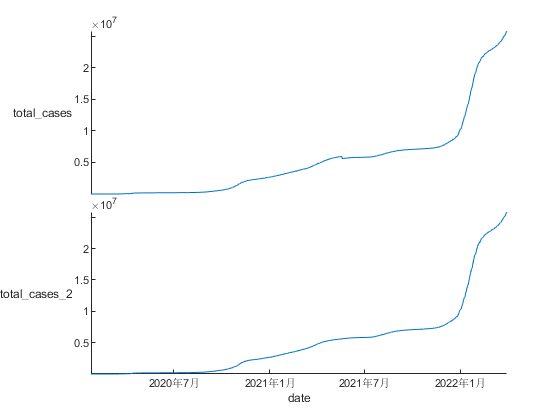

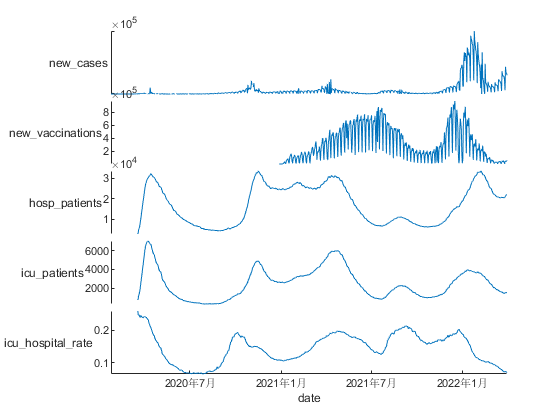

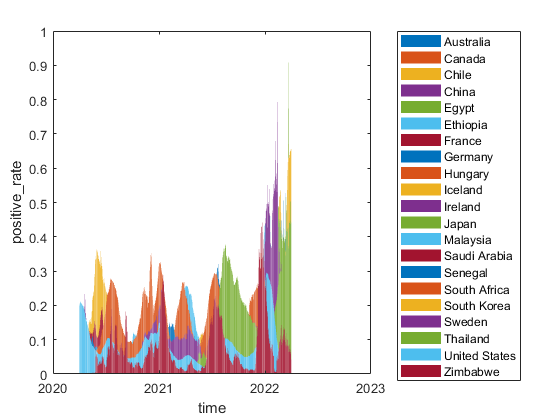

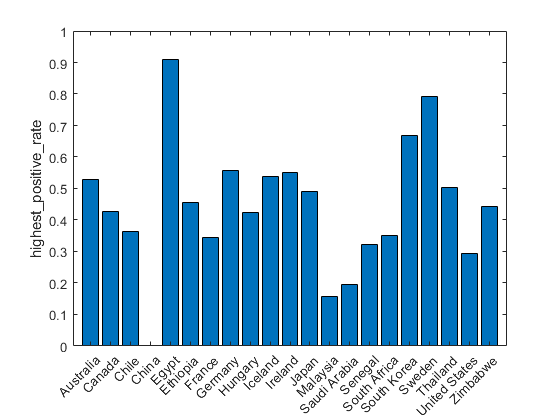

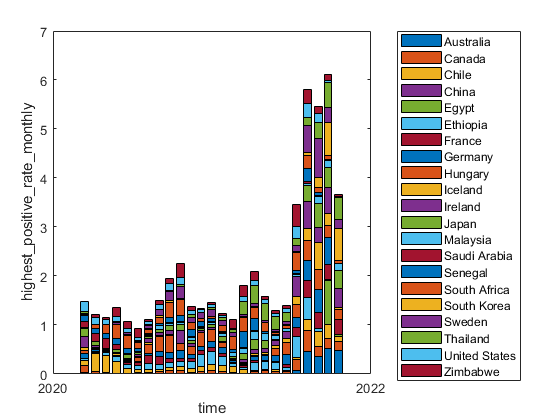

   0.050516809263215

   0.323391189157043

   0.869391266286694

   0.698677279775290

   0.210970222680379

   0.253667350602448

   0.880391652617718

   0.066094252556610

   0.188611402595327



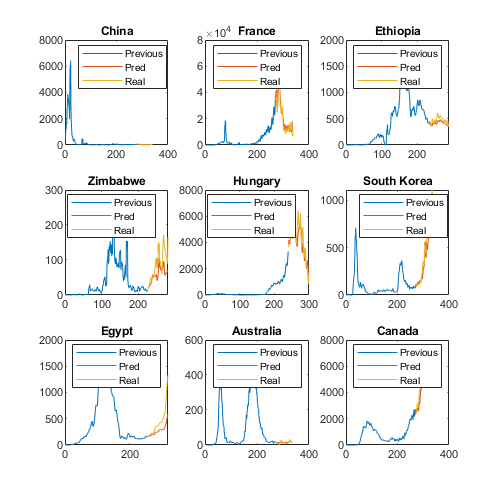

% 
Y = pdist(score);
Y = squareform(Y);
Z = linkage(Y);
dendrogram(Z, 'Labels', country_daily{:,'location'}, 'ColorThreshold', 200);